# Regelungstechniklabor Laborversuch 5 - Schwebekugel

m=10e-3;
c_i=0.01;
c_y=0.01e-2;
L=0.1;
R=5;

## Aufgabe 1

#### a)


$$G\left(s\right)=\frac{c_i }{R+\mathrm{Ls}}\cdot \frac{1}{\mathrm{ms²}-c_y }$$


Aus der Übertragungsfunktion erhalten wir die Pole:

${\mathrm{Pol}}_1 =-\frac{R}{L}$ und ${\mathrm{Pol}}_{2,3} =\pm \sqrt{\frac{c_y }{m}}$

#### b)

Da ${\mathrm{Pol}}_2 =+\sqrt{\frac{c_y }{m}}$  größer 0 ist, ist die Regelstrecke instalbil.

#### c)

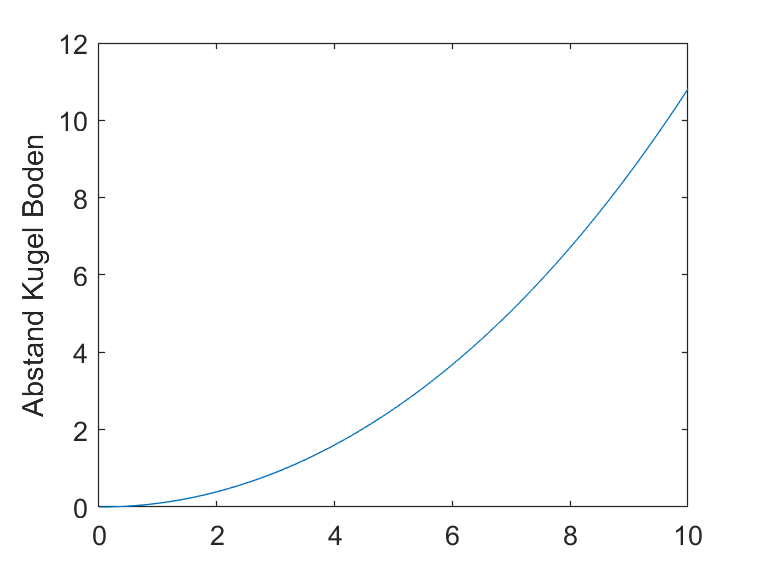

simOut = sim('L5A1.slx');
figure
plot(get(simOut.logsout,"y").Values.Time,get(simOut.logsout,"y").Values.Data);
ylabel('Abstand Kugel Boden')

#### e)

Die Regelstrecke ist instabil.

## Aufgabe 2 - Regelkreis mit P-Regler

#### b)

K_rs=[0.05,0.04,0.5,1,5,20];
figure
hold on
for i = 1:5
    K_r=K_rs(i)
    simOut = sim('L5A2.slx');
    plot(get(simOut.logsout,"y").Values.Time,get(simOut.logsout,"y").Values.Data);
end

K_r = 0.0500

K_r = 0.0400

K_r = 0.5000

K_r = 1

K_r = 5

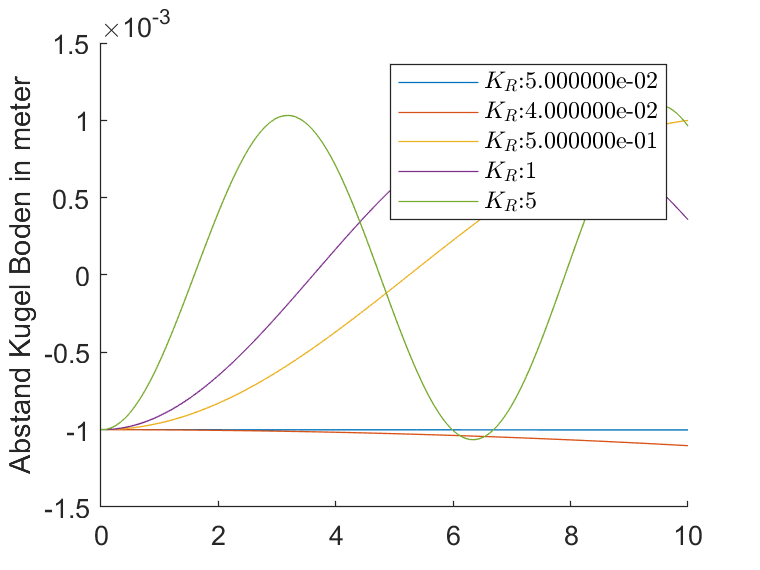

hold off
ylabel('Abstand Kugel Boden in meter')
legend(sprintf("$K_R$:%i",K_rs(1)), ...
    sprintf("$K_R$:%i",K_rs(2)), ...
    sprintf("$K_R$:%i",K_rs(3)), ...
    sprintf("$K_R$:%i",K_rs(4)), ...
    sprintf("$K_R$:%i", K_rs(5)), ...
    'Interpreter','latex')

#### c)

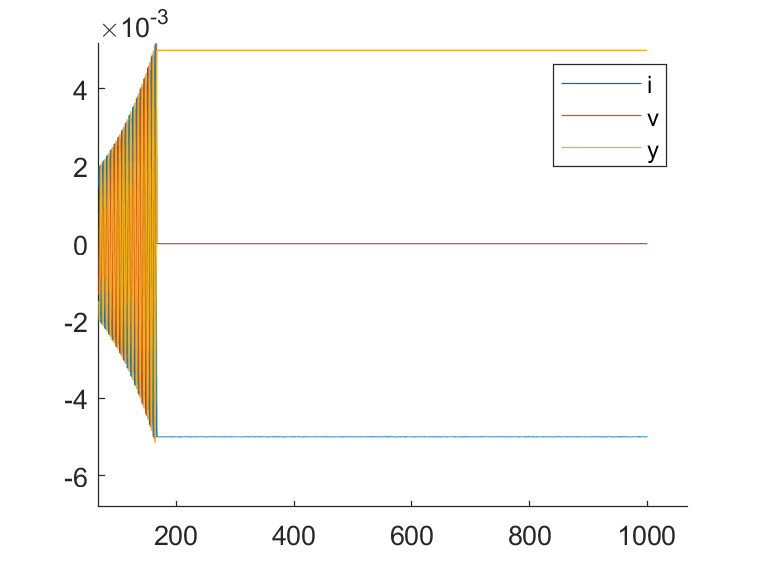

i=0.05;
simOut = sim('L5A2.slx',1000);
while max(get(simOut.logsout,"y").Values.Data)<1e-3
    K_r=i
    i=i+0.00001;
    simOut = sim('L5A2.slx',1000);
end
% simOut = sim('L5A2.slx',10000);
figure
hold on
plot(get(simOut.logsout,"i").Values.Time,get(simOut.logsout,"i").Values.Data);
plot(get(simOut.logsout,"v").Values.Time,get(simOut.logsout,"v").Values.Data);
plot(get(simOut.logsout,"y").Values.Time,get(simOut.logsout,"y").Values.Data);
hold off
legend("i","v","y");